# Confusion matrices

You are working on a project to classify between cancerous (malignant) and healthy (benign) biopsies. Your colleague has shared a trained classifier with you and some previously unseen testing data. You can assume the data has been properly prepared:

clear all;
load('classifiers.mat', 'm_nb', 'test_examples', 'test_labels');

Your task is to generate and analyse a confusion matrix for the classifier.

Marks are available for:

- Using the classifier to predict labels for the test data [2 marks]

- Comparing the predictions with the true labels to generate a confusion matrix [2 marks]

- Explaining the meaning (in code comments) of each of the 4 entries in the confusion matrix [4 marks]

- Using the 4 entries to compute the overall classification accuracy [2 marks]

- Computing the true positive rate (TPR) for the classifier, taking "malignant" as the positive class [3 marks]

- Computing the false positive rate (FPR) for the classifier, taking "malignant" as the positive class [3 marks]

- Commenting your code to explain the steps you are taking [4 marks]

[Total: 20 marks]

% add as many lines of code as you need below:

%use m_nb classifier to predict labels for the test data
predictions = m_nb.predict(test_examples)

predictions = 142×1 categorical array
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Malignant 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Benign 
     Malignant 
     Benign 
     Malignant 
     Benign 
     Benign 
     Malignant 
     Malignant 
     Benign 
     Malignant 



% output a confusion matrix:
[c,order] = confusionmat(test_labels, predictions)

c =     83     2
     4    53


order = 2×1 categorical array
     Benign 
     Malignant 


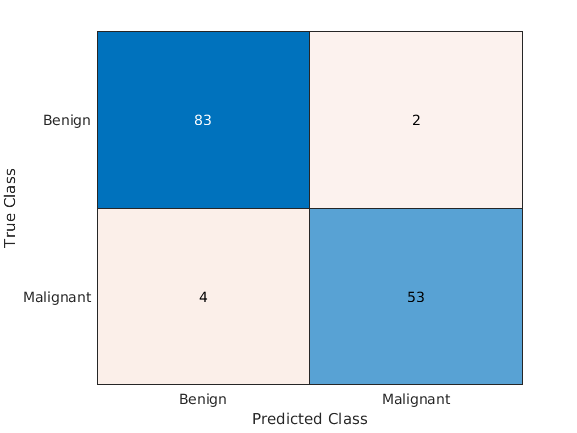


% outputs a labelled chart of the confusion matrix, the diagonal from top
% left down to bottom right are the labels that were predicted correctly (colored in blue)
% and the diagonals from bottom left to top right are the labels that were
% predicted incorrectly (colored in red), the value given represents how many times that
% label was predicted
c_chart = confusionchart(test_labels, predictions);


%calculate overall classification accuracy
p = sum(diag(c)) / sum(c(1:1:end))

p = 0.9577


%calculate TPR
TP = c(2,2); %find true positives by indexing confusion matrix

TP = 53

FN = c(2,1; %find false negatives by indexing confusion matrix

FN = 4

TPR = (TP)/(TP+FN) %calculate TPR by calculating the proportion of positive examples that where correctly classified

TPR = 0.9298


%calculate FPR
FP = c(1,2); %find false positives by indexing confusion matrix

FP = 2

TN = c(1,1); %find true negatives by indexing confusion matrix

TN = 83

FPR = (FP)/(FP+TN) %calculate FPR by calculating the proportion of negative examples that incorrectly classified as positive

FPR = 0.0235